### 2.2.1. Implementing a Baseband Communication System  

Sampling the Signal

Fs = 6000; %The sampling frequency used to sample the audio
qbits = 8; %The number of bits used to encode a single sample of the audio
recObj = audiorecorder(Fs,qbits,1); %Starting the audio recorder object
disp('Start speaking.') %Recording audio fro 5 seconds

Start speaking.


recordblocking(recObj, 5);
disp('End of Recording.');

End of Recording.


audio_samples = getaudiodata(recObj); %array containing samples of the recorded audio

Quantizing

siz = size(audio_samples); %Quantizing the audio samples (Each sample is quantized with 8 bits)
size_audio_samples = siz(1);
number_of_bits = qbits*size_audio_samples;
bit_stream = zeros([1,number_of_bits]); %array which is used to store the binary representation
                                        %of the recorded audio

for i = 1:size_audio_samples
    num = audio_samples(i,1);
    if(num<0)
        bit_stream(1,(i-1)*qbits+1) = 1;
    else
        bit_stream(1,(i-1)*qbits+1) = 0;
    end
    num = abs(num);
    for j = 2:qbits
        num = 2*num;
        if(num>=1)
            bit_stream(1,(i-1)*qbits+j) = 1;
            num = num - 1;
        else
        bit_stream(1,(i-1)*qbits+j) = 0;
        end
    end
end

Encoding

samples_per_bit = 100;      %Number of samples used to approximate the
                            %sinosoid for a single bit (We approximate
                            % sin(Wc*t+phase0) or sin(Wc*t+phase1) with 100
                            % bits in this case
Amplitude = -5; %Amplitude in decibels
sampling_rate = Fs*qbits*samples_per_bit;   %The sampling rate used to represent the 
                                            % anlog singal in MATLAB

fc = sampling_rate/100; % frequency of the sinosoid
Wc = 2*pi*fc;
delt = 1/sampling_rate; %Sample time period
phase0 = pi;
phase1 = 0;

number_of_samples = number_of_bits*samples_per_bit; %Total number of samples of the transmitted signal
X = zeros([1,number_of_samples]); %X(t) − This array is used to store the transmitted analog signal

%This section does the encoding which is described previously

power = 10^(Amplitude/20); %Signal power in watts.
t_bit = delt:delt:delt*samples_per_bit;
bit1 = sqrt(power)*sin(Wc*t_bit+phase1); %Representation of bit 1
bit0 = sqrt(power)*sin(Wc*t_bit+phase0); %Representation of bit 0
for i = 1:number_of_bits
    if(bit_stream(i)==1)
        X(samples_per_bit*(i-1)+1:samples_per_bit*i) = bit1;
    else
        X(samples_per_bit*(i-1)+1:samples_per_bit*i) = bit0;
    end
end


Task 5

arr_X=zeros([21,number_of_bits])
for k=-10:10    
    samples_per_bit = 100;      %Number of samples used to approximate the
                                %sinosoid for a single bit (We approximate
                                % sin(Wc*t+phase0) or sin(Wc*t+phase1) with 100
                                % bits in this case

    sampling_rate = Fs*qbits*samples_per_bit;   %The sampling rate used to represent the 
                                                % anlog singal in MATLAB
    
    fc = sampling_rate/100; % frequency of the sinosoid
    Wc = 2*pi*fc;
    delt = 1/sampling_rate; %Sample time period
    phase0 = pi;
    phase1 = 0;
    
    number_of_samples = number_of_bits*samples_per_bit; %Total number of samples of the transmitted signal
    X = zeros([1,number_of_samples]); %X(t) − This array is used to store the transmitted analog signal
    
    %This section does the encoding which is described previously
    
    power = 10^(k/20); %Signal power in watts.
    t_bit = delt:delt:delt*samples_per_bit;
    bit1 = sqrt(power)*sin(Wc*t_bit+phase1); %Representation of bit 1
    bit0 = sqrt(power)*sin(Wc*t_bit+phase0); %Representation of bit 0
    for i = 1:number_of_bits
        if(bit_stream(i)==1)
            X(samples_per_bit*(i-1)+1:samples_per_bit*i) = bit1;
        else
            X(samples_per_bit*(i-1)+1:samples_per_bit*i) = bit0;
        end
    end
    arr_X(k+11)=X;
end

Transmition

arr_Y=zeros([21,number_of_bits])
for i=1:21
    att = 0.8;  %attenuation factor
    mu = 0;     %Paramenters of the noise signal (mu, and sigma). We model noise as a Gaussian random variable
    sigma = 1;
    N = normrnd(mu,sigma,1,samples_per_bit*number_of_bits); %N(t) − noise signal
    X_hat = att*i + N; %signal after noise 
    % Filtering Effect
    fc_butter = fc*25;
    [fil_b,fil_a] = butter(10,fc_butter/(sampling_rate/2));
    arr_Y(i) = filter(fil_b,fil_a,X_hat);%recived signal after bandwidth limitation (filtering)
end



Decoding

decoded_bit_stream = zeros([1,number_of_bits]); %The array to store the decoded bit stream
arr_x_decoded=zeros([21,number_of_bits])
H = [cos(Wc*delt*[1:samples_per_bit]'),sin(Wc*delt*[1:samples_per_bit]')]; %Phase estimation matrox

for i=1:21
    for i = 1:number_of_bits %This loop deals with the phase estimation
        f = inv(H'*H)*H'*Y((i-1)*samples_per_bit+1:i*samples_per_bit)';
        decoded_phase = 0;
        if(f(2) == 0)
            if(f(1) >= 0)
                decoded_phase = pi/2;
            else
                decoded_phase = -pi/2;
            end
        else
            decoded_phase = atan(f(1)/f(2));
            if(f(1)<=0 & f(2)<0)
                decoded_phase = decoded_phase--i;
            elseif(f(1)>0 & f(2)<0)
                decoded_phase = decoded_phase+pi;
            end
        end
        p0 = min(abs(decoded_phase - phase0),2*pi-abs(decoded_phase - phase0));
        p1 = min(abs(decoded_phase - phase1),2*pi-abs(decoded_phase - phase1));
    
        if(p0<p1)
            decoded_bit_stream(i) = 0;
        else
            decoded_bit_stream(i) = 1;
        end
    end
end

Reconstructing

decoded_audio_samples = zeros([size_audio_samples,1]);

    for i=1:size_audio_samples
        st = 0.5;
        for j=2:qbits
            decoded_audio_samples(i) = decoded_audio_samples(i)+st*decoded_bit_stream((i-1)*qbits+j);
            st = st/2;
        end
        if(decoded_bit_stream((i-1)*qbits+1) == 1)
            decoded_audio_samples(i) = -decoded_audio_samples(i);
        end
    end


Playing the Reconstructed audio


pause(10);
sound(5*decoded_audio_samples, Fs);


### 2.2.2 Comparing Original Singnal and Reconstructed Signal

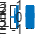


figure(1)
subplot(1,2,1)
plot(audio_samples)
title('Original Audio Signal')
xlabel('t (s)')
ylabel('Amplitude')
subplot(1,2,2)
plot(decoded_audio_samples);
title('Decoded Audio Signal')
xlabel('t (s)')
ylabel('Amplitude')

### 2.2.3 Comparing Original and Transmitted signal in Frequency Domain

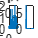


L_1 = size_audio_samples;
Audio_freq = fft(audio_samples);
Audio_freq_norm = abs(Audio_freq/L_1);
Audio_freq_norm_one = Audio_freq_norm(1:L_1/2+1);
Audio_freq_norm_one(2:end-1) = 2*Audio_freq_norm_one(2:end-1);

L_2 = samples_per_bit*number_of_bits;
X_freq = fft(X);
X_freq_norm = abs(X_freq/L_2);
X_freq_norm_one = X_freq_norm(1:L_2/2+1);
X_freq_norm_one(2:end-1) = 2*X_freq_norm_one(2:end-1);

f_1 = Fs*(0:(L_1/2))/L_1;
f_2 = sampling_rate*(0:(L_2/2))/L_2;

figure(2)
subplot(1,2,1)
plot(f_1,Audio_freq_norm_one);
title('Single−Sided Amplitude Spectrum of the Original Audio Stream');
xlabel('f (Hz)')
ylabel('|P1(f)|')

subplot(1,2,2)
plot(f_2,X_freq_norm_one);
title('Single−Sided Amplitude Spectrum of X(t)')
xlabel('f (Hz)')
ylabel('|P1(f)|')

Calculating the BER

error_bits = bit_stream~=decoded_bit_stream

error_bits = 1×240000 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   0   0   0   1   0   0   0   0   0   0   0   1   0   0   0   1   1   1   0   0   0   0   1   0   0   0   0   0   0   0   1   0   0   1


BER=sum(error_bits(:)==1)/numel(error_bits)

BER = 0.1964